# Ejercicio 8

Picture 1 to train classifier:

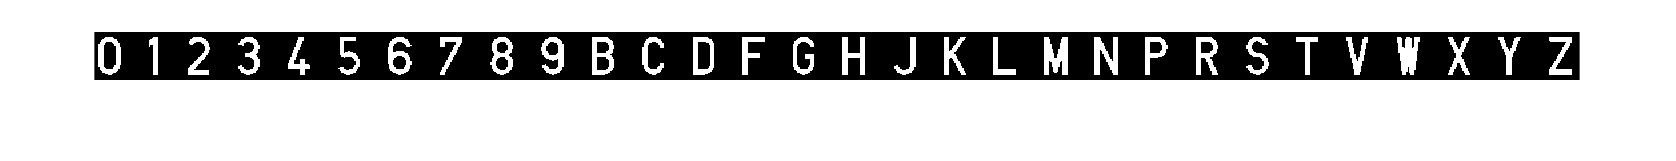

I = rgb2gray(imread('Joc_de_caracters.jpg'));
BI = I < 128; % lletres estan en negre
imshow(BI);

CC = bwconncomp(BI);
OUT = {'0' '1' '2' '3' '4' '5' '6' '7' '8' '9' 'B' 'C' 'D' 'F' 'G' 'H' 'J' 'K' 'L' 'M' 'N' 'P' 'R' 'S' 'T' 'V' 'W' 'X' 'Y' 'Z'};

Load reference picture to test classifier

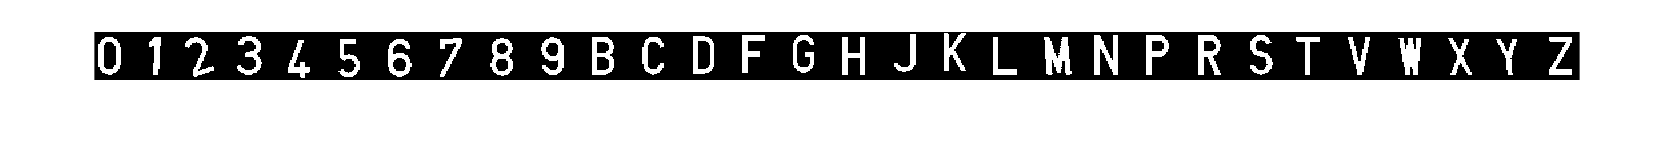

I2 = rgb2gray(imread('Joc_de_caracters_deformats.jpg'));
BI2 = I2 < 128; % separem el background
%SE = strel('disk', 1);
%BI2 = imopen(BI2,SE);
figure;imshow(BI2);

CC2 = bwconncomp(BI2);



%try different combinations in for loop of folowing parameters:
desc = ["Circularity" "Eccentricity" "EulerNumber" "Extent" "Solidity"] ;  
%desc = ["Extent" "Solidity"] ;  

%should these be used?
%MaxFeretProperties - MaxFeretAngle
%MinFeretProperties - MinFeretAngle

%making the for loop work in binary to activate and deactivate fields
n = 2^length(desc);
d_array = [1:n]';
binary = dec2bin(d_array);

%best combination and its values
bestCombo = [];
bestMean = 0;
bestSD = 100000;
bestTable = table();
bestScore = 0;
numCorrectLabels = 0;
bestClassifier = 0;

for i=1:n-1 %because we don't want to test for when chosen = [] (last case)
    chosen = [];
    currentBin = binary(i,:);
    %currentBin
    length(currentBin);
    for j=0:length(desc)-1 
        currentBin(end-j);
        if currentBin(end-j) == '1'
            desc(:,end-j);
            chosen = [chosen, desc(:,end-j)];
        end
    end
    %train classifier
    props = regionprops(CC,chosen);
    X = cell2mat(struct2cell(props))';
    Classifier = TreeBagger(100,X,OUT');

    %test with reference
    props2 = regionprops(CC2,chosen);
    X2 = cell2mat(struct2cell(props2))'; 

    [label,score] = predict(Classifier,X2);

    % mostrem el resultat mes probable i la seva puntuació (score)
    maxScore = max(score,[],2);
    T = table(Classifier.ClassNames,label,maxScore,'VariableNames',{'Name','Label','Score'});
    currMean = mean(maxScore);
    currSD = std(maxScore);
    currScore = currMean-currSD;
    currCorrectLabels = sum(strcmp(Classifier.ClassNames, label));
    
    %if values we measure better, replace and save info about combo
    if (currCorrectLabels > numCorrectLabels || currCorrectLabels == numCorrectLabels & currMean > bestMean)
        bestTable = T;
        bestCombo = chosen;
        bestMean = currMean;
        bestSD = currSD;
        bestScore = currScore;
        numCorrectLabels = currCorrectLabels;
        bestClassifier = Classifier;
    end  
end
bestTable

bestTable = 30×3 table
    Name     Label    Score
    _____    _____    _____

    {'0'}    {'0'}    0.69 
    {'1'}    {'1'}     0.6 
    {'2'}    {'2'}    0.47 
    {'3'}    {'C'}    0.27 
    {'4'}    {'4'}    0.48 
    {'5'}    {'5'}     0.7 
    {'6'}    {'6'}    0.68 
    {'7'}    {'7'}    0.48 
    {'8'}    {'8'}    0.49 
    {'9'}    {'9'}     0.5 
    {'B'}    {'B'}    0.59 
    {'C'}    {'C'}    0.62 
    {'D'}    {'D'}    0.61 
    {'F'}    {'F'}    0.58 
    {'G'}    {'G'}    0.63 
    {'H'}    {'H'}     0.6 


bestCombo

bestCombo = 1×3 string array
    "Solidity"    "EulerNumber"    "Eccentricity"


bestMean

bestMean = 0.5437

bestSD

bestSD = 0.1035

numCorrectLabels

numCorrectLabels = 28

Do not include descriptors that vary with the font size or the position of the character in the image in the analysis, ()

`(Area)  `

`(BoundingBox)`

`(Centroid)`

`Circularity                     Useful`

`(ConvexArea)`

`(ConvexHull)`

`(ConvexImage)`

`Eccentricity`

`(EquivDiameter)`

`EulerNumber                     Useful`

`Extent`

`(Extrema)`

`(FilledArea)`

`(FilledImage)`

`(Image)`

`(MajorAxisLength)`

`MaxFeretProperties - MaxFeretAngle`

`MinFeretProperties - MinFeretAngle`

`(MinorAxisLength)`

`(Orientation)`

`(Perimeter)`

`(PixelIdxList)`

`(PixelList)`

`Solidity                    Useful for F B 7`

`(SubarrayIdx)`

`Interesting links:`

[`https://uk.mathworks.com/help/vision/ref/ocr.html`](https://uk.mathworks.com/help/vision/ref/ocr.html) 

[`https://uk.mathworks.com/help/vision/ug/digit-classification-using-hog-features.html`](https://uk.mathworks.com/help/vision/ug/digit-classification-using-hog-features.html) 

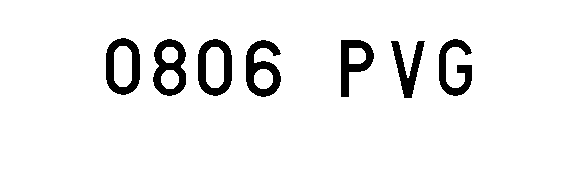



%classify
I_license = imread('pablito.png');
I_license = imbinarize(rgb2gray(I_license));
imshow(I_license)

CC3 = bwconncomp(~I_license);

props3 = regionprops(CC3,bestCombo);
X3 = cell2mat(struct2cell(props3))'; 

[label,score] = predict(bestClassifier,X3);


% mostrem el resultat mes probable i la seva puntuació (score)
table(label,max(score,[],2),'VariableNames',{'Label','Score'})

ans = 7×2 table
    Label    Score
    _____    _____

    {'0'}    0.69 
    {'8'}    0.56 
    {'0'}    0.69 
    {'6'}    0.68 
    {'P'}    0.72 
    {'V'}    0.66 
    {'G'}     0.7 
